## Results - Collision Detection

Here we implement collision detection of the manipulator in the prescence of a moving spherical obstacle. As the manipulator moves between two configurations, we color the links red when it is too close/inteferes with the obstacle. 

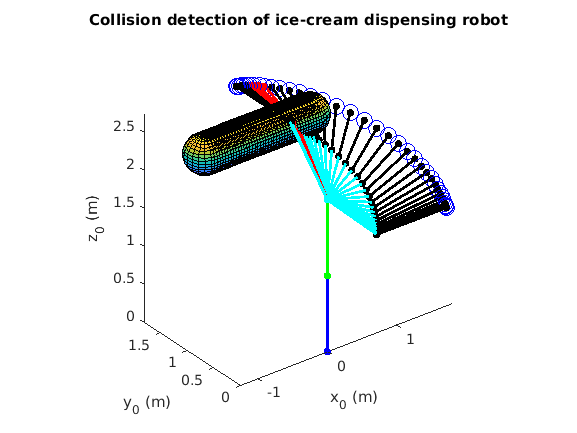

clear all 
close all

% Link parameters
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;

interval = 20; % Specify number of points in each trajectory

% Specify start and desired joint positions
q = [0 pi/2; % q1_start, q1_desired
    0 0; % q2_start, q2_desired
    0 pi/2]; % q3_start, q3_desired

% Note q4 is calculated below to ensure final link is always parallel to
% ground

segmentsperlink = 3; % Specify how many segments per link for collision checking
t0=0; % Start time (can change to any positive number)
alpha=10; % Max angular acceleration of all joints (deg/s^2)

% Generate trajectory in Traj_mat matrix, where ith row corresponds to ith
% joint
for i=1:length(q)
    q0=q(i,1);
    qf=q(i,2);
    [t,traj]=trajplan(q0,qf,t0,alpha,interval);
    Traj_mat(i,:)=traj; 
end

% Solve for joint 4 trajectory based on geometry:
Traj_mat(4,:)= pi/2 - gamma - Traj_mat(2,:) - Traj_mat(3,:) ;

matlen=length(Traj_mat);
% Specify motion of center of sphere (x,y,z)
pos=[linspace(-1,0.5,matlen); linspace(1,1,matlen);linspace(2.5,2.5,matlen)];
rad=0.25; % Sphere radius


% Run main loop. 
for i=1:length(Traj_mat)
    % Specify DH table. 
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    
    % Specify theta from min time trajectory generated earlier.
    theta1=Traj_mat(1,i); theta2=Traj_mat(2,i); theta3=Traj_mat(3,i); theta4=Traj_mat(4,i);
    theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
    
    % Compute FK and output H matrix and location of each frame in P_vec:
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    
    % Check if in collision with moving sphere:
    [inCol, index]=check_collision(P_vec,pos(:,i),rad,segmentsperlink);
    
    % Plot the robot links:
    plot_link(P_vec,i,length(Traj_mat),index); 
    
    % Plot the obstacle:
    plot_sphere(pos(:,i),rad)

end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Collision detection of ice-cream dispensing robot')

## FUNCTIONS

function [tvec, traj] = trajplan(q0,qf,t0,alpha,interval)
% Computes minimal time trajectory 
    ts=sqrt((qf-q0)/alpha);
    t1=linspace(0,ts,interval);
    t2=linspace(ts,2*ts,interval);
    ang_pos1 = 0.5*alpha*t1.^2;
    ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
    tvec=[t0+t1,t0+t2];
    traj=[ang_pos1,ang_pos2];
end

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
% This function calculates the homogeneous transformation matrix H using DH
% convention input parameters and outputs the final H^0_n, the position of all frames
% (P_vec), and all the H matrices.
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));
    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

function plot_link(P_vec,current,end_condition,index)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    if index==0
        h1=plot3(A(1:2),B(1:2),C(1:2),'b.-','MarkerSize',12,'LineWidth',2);
        h2=plot3(A(2:3),B(2:3),C(2:3),'g.-','MarkerSize',12,'LineWidth',2);
        h3=plot3(A(3:4),B(3:4),C(3:4),'c.-','MarkerSize',12,'LineWidth',2);
        h4=plot3(A(4:5),B(4:5),C(4:5),'k.-','MarkerSize',12,'LineWidth',2);
    else
        h1=plot3(A,B,C,'r.-','MarkerSize',12,'LineWidth',2);
    end
    hold on
    h2=plot3(P_vec(1,end),P_vec(2,end),P_vec(3,end),'bo','MarkerSize',12);
    axis equal
    pause(0.1)    
end

function plot_sphere(pos,rad)
    [X,Y,Z] = sphere;
    h1=surf(X*rad+pos(1),Y*rad+pos(2),Z*rad+pos(3));
    pause(0.1)
    hold on
end

function [inCol, index] = check_collision(P_vec,pos,rad,segmentsperlink)
    
    links=length(P_vec);
    inCol=zeros(1,4);
    index=0;
    d=zeros(links,segmentsperlink);
    for i=1:links
        if i==1
            x_pos = linspace(0,P_vec(1,i),segmentsperlink);
            y_pos = linspace(0,P_vec(2,i),segmentsperlink);
            z_pos = linspace(0,P_vec(3,i),segmentsperlink);
            d(1,:) = sqrt((x_pos - pos(1)).^2 + (y_pos - pos(2)).^2 + (z_pos - pos(3)).^2);
        else 
            x_pos = linspace(P_vec(1,i-1),P_vec(1,i),segmentsperlink);
            y_pos = linspace(P_vec(2,i-1),P_vec(2,i),segmentsperlink);
            z_pos = linspace(P_vec(3,i-1),P_vec(3,i),segmentsperlink);
            d(i,:) = sqrt((x_pos - pos(1)).^2 + (y_pos - pos(2)).^2 + (z_pos - pos(3)).^2);
        end
        
    end
    d=transpose(d);
    minperlink = min(d);
    for j=1:links
        if minperlink(j)<rad
            inCol(j)=1;
            index=j;
        end
    end

end